# Experimental methods in psychological sciences

Course for ENS-PSL cognitive science masters program

Part 2: Psychophysics and signal detection theory

This section is written by Tarryn Balsdon

## Section 2. Psychometrics and the internal value

Last week we examined two key concepts of Signal Detection Theory:

- External signals are added on a background of 'noise' meaning that we do not experience discrete states, rather,** our psychological experience varies along some internal continuum**

-  We infer the cause of our psychological experience (whether an external signal was presented) by placing **a criterion** on this internal continuum, and the placement of this criterion is under our **strategic control**

This week we will delve deeper into what this internal continuum is, in contexts beyond signal detection, and how we measure this continuum.

### a. My favourite stimulus

My favourite stimulus is the Gabor patch. The Gabor patch is named after Dennis Gabor, who won the Noble prize in Physics in 1971 for the "invention and development of the holographic method". The Gabor patch is created using a 'sinusoidal filter', the 1-dimensional version of which was proposed by Dennis Gabor, hense the name. We like Gabors because they drive early visual neuronal activity in a controlled fashion. Neurons in early visual cortex like lines/edges which appear from a change in luminance (e.g. which to black). The magnitude of the change in luminance is called the contrast. Neurons in early visual cortex respond more to greater contrast. They also have a preference for orientation - some like vertical things, some like horizontal things, and others like stuff in between. They also have a 'receptive field' which corresponds to some location in space, they respond as a function of the contrast and orientation of the light at that location. This means that there are three properties of the Gabor patch which can be carefully controlled, which drive differences in neural firing in early visual cortex: contrast, orientation, and spatial frequency.

Spatial frequency is easiest to describe by demonstration.

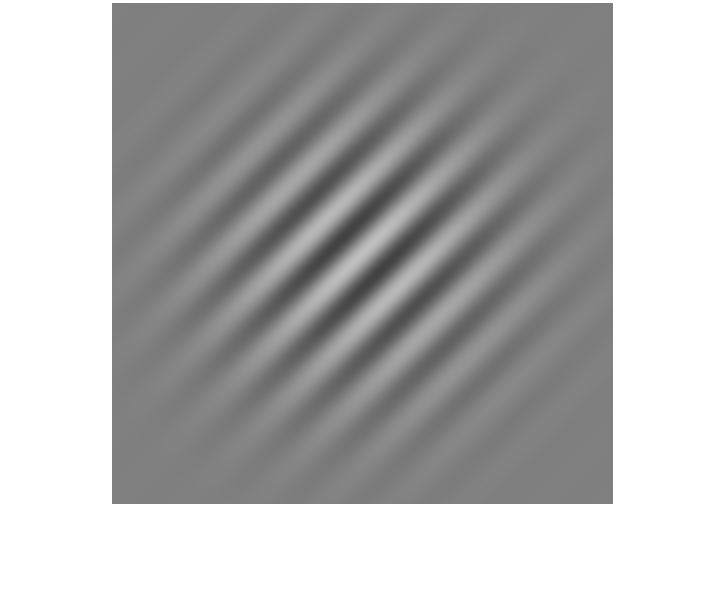


% properties of the Gabor patch - you can play with this
image_size = [501,501]; % pixels

orientation = 45; % in degrees
contrast = 0.5; 
num_cycles = 10; % the number of black to white bits
spatial_frequency = num_cycles/image_size(1);
phase = 1; % this shifts the cycles
sc = image_size(1)/5; % this is for the gaussian envelope

% first we have a 2D map of locations in the image (the x and y
% coordinates)

[x,y] = meshgrid((1:image_size(1))-(image_size(1)+1)/2, (1:image_size(2))-(image_size(2)+1)/2);
% x and y should go from -250 to 250


% convert angle from deg to rad
orientation = orientation*pi/180;

% apply the sinusoidal filter
u = sin(orientation)*x+cos(orientation)*y;

period = 1/spatial_frequency;
gaborimg = cos(2*pi*(u/period+phase));

% next we apply a 2D gaussian 'envelope' (this blurs the edges)
r = sqrt(x.^2+y.^2); % radius
gaborimg = gaborimg.*normpdf(r,0,sc)/normpdf(0,0,sc);

% normalise
gaborimg = gaborimg - mean(mean(gaborimg));
gaborimg = gaborimg./(max([max(max(gaborimg)),-min(min(gaborimg))]));

% michaelson contrast - there are different types of contrast
scale = 0.5;
gaborimg = (gaborimg*contrast*scale)+(1/2);

figure
imshow(gaborimg)

The Gabor patch has a number of stimulus properties that can be finely manipulated, and each manipulation has a systematic affect on the neural response and our psychological experience of the stimulus.

### b. The psychometric function for detection

Last week we examined the simple task of detecting a signal. The signal is added on a background of noise, making it difficult to judge whether our psychological experience resulted from the presence of a signal or noise alone. In a yes/no task one must set a criterion where if the internal value of our psychological experience falls above this criterion, one says that a signal was present. With the Gabor patch, we can manipulate the signal strength using the contrast. At 0 contrast the Gabor is absent, as we increase the contrast we increase the signal strength. In an experiement we can present the observer with different signal strengths and see how they respond.

Let's simulate and plot this

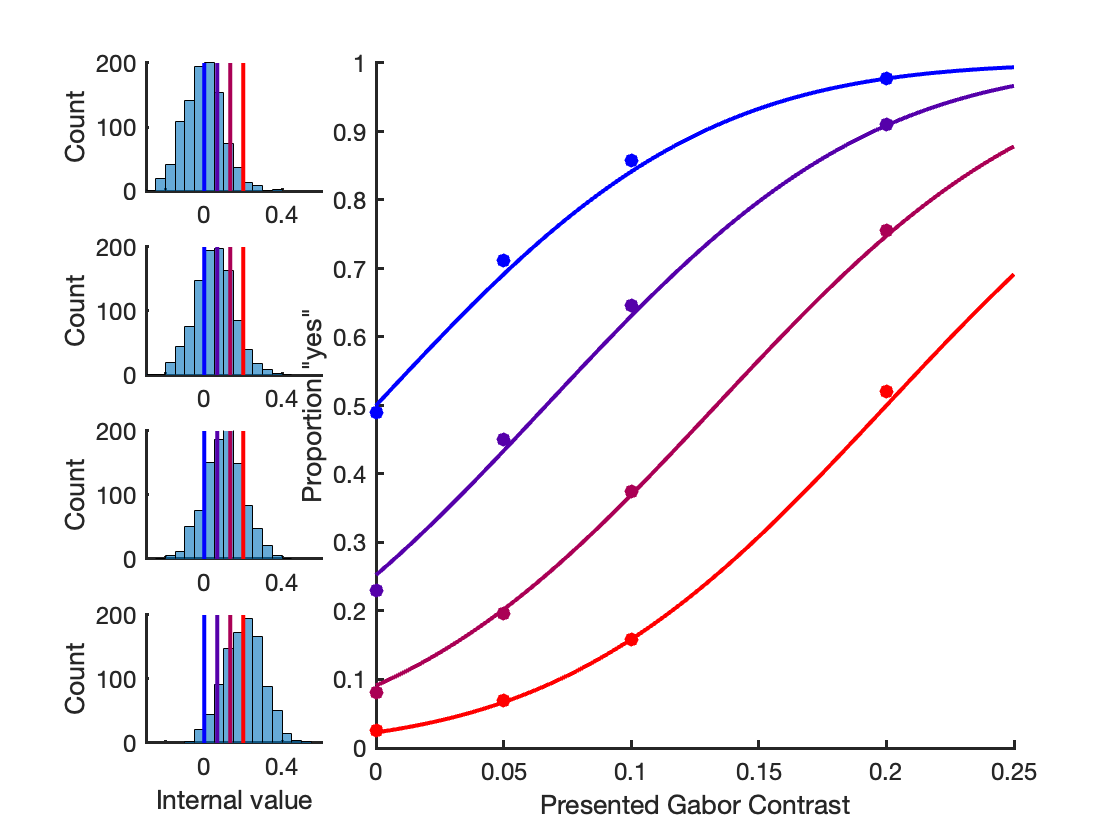

% The contrast varies on each trial:
signal_strengths = [0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate lots of trials
ntrials = 1000; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;

% the observer compares the internal value to a criterion
% compare different criteria
ncriteria = 4;
criteria = linspace(0,0.2,ncriteria);

% pre-allocate
proportion_yes = nan(nsignals,ncriteria);

% loop to calculate the proportion of 'yes' responses
for ci = 1:ncriteria
    
    proportion_yes(:,ci) = mean(samples > criteria(ci),1); % the average  over trials
    
end

% plot
% colours for the criteria
mycolours = [linspace(0,1,ncriteria)',zeros(ncriteria,1),linspace(1,0,ncriteria)'];
figure;
for si = 1:nsignals
    subplot(4,4,(si*4)-3);
    hold on
    %histogram(samples(:,si),'BinWidth',0.05,'DisplayStyle','stairs','LineWidth',2)
    histogram(samples(:,si),'BinWidth',0.05)
    for ci = 1:ncriteria
        plot([criteria(ci),criteria(ci)],[0,200],'Color',mycolours(ci,:),'LineWidth',2)
    end
    ylabel('Count')
    axis([-0.3,0.6,0,200])
    makeMyPlotPretty
end

xlabel('Internal value')


subplot(4,4,[2:4,6:8,10:12,14:16])
hold on
xs = linspace(0,0.25,100);
for ci = 1:ncriteria
    
    scatter(signal_strengths,proportion_yes(:,ci),50,mycolours(ci,:),'filled')
    
    % the theoretical curve
    ys = normcdf(xs,criteria(ci),noise_sd);
    plot(xs,ys,'Color',mycolours(ci,:),'LineWidth',2)
    
end

xlabel('Presented Gabor Contrast')
ylabel('Proportion "yes"')
makeMyPlotPretty

The plots on the left show histograms of the internal values (signal/contrast + noise) against the different criteria. The plot on the right shows how the proportion of 'yes' responses increases with increasing contrast, where the lines plot the theoretical psychometric functions based on the internal noise of the observer.

**TAKE-AWAY:** The principles of signal detection theory generalise to predict the psychometric function.

The observer with the liberal criterion for responding 'yes' (blue) responds 'yes' 50% of the time when the contrast is actually 0 (signal-absent), but close to 100% of the time when the Gabor contrast is 0.2. The observer who responds with the conservative criterion (red) almost never responds 'yes' when the contrast is 0, but only responds 'yes' 50% of the time when the contrast is 0.2. You should also see the shapes of the lines as somewhat shifted as the criterion becomes more liberal. This is a bit difficult to see because we don't get the full extent of the curve (from 0 to 1) in any observer.

To ensure you see the full extent of the curve in a detection task, you need to use a 2AFC design (with carefully chosen stimulus values).

In a 2AFC task, we present two intervals, one containing the signal, and the observer chooses the interval with the greater internal value as signal present. For a two-spatial-interval design, we can tell the observer the Gabor will be presented on the left or the right of the screen, and ask them to report left/right. (a two-temporal interval design could have a sequential presentation of intervals, marked by an auditory beep, for example).

Lets simulate and plot this.

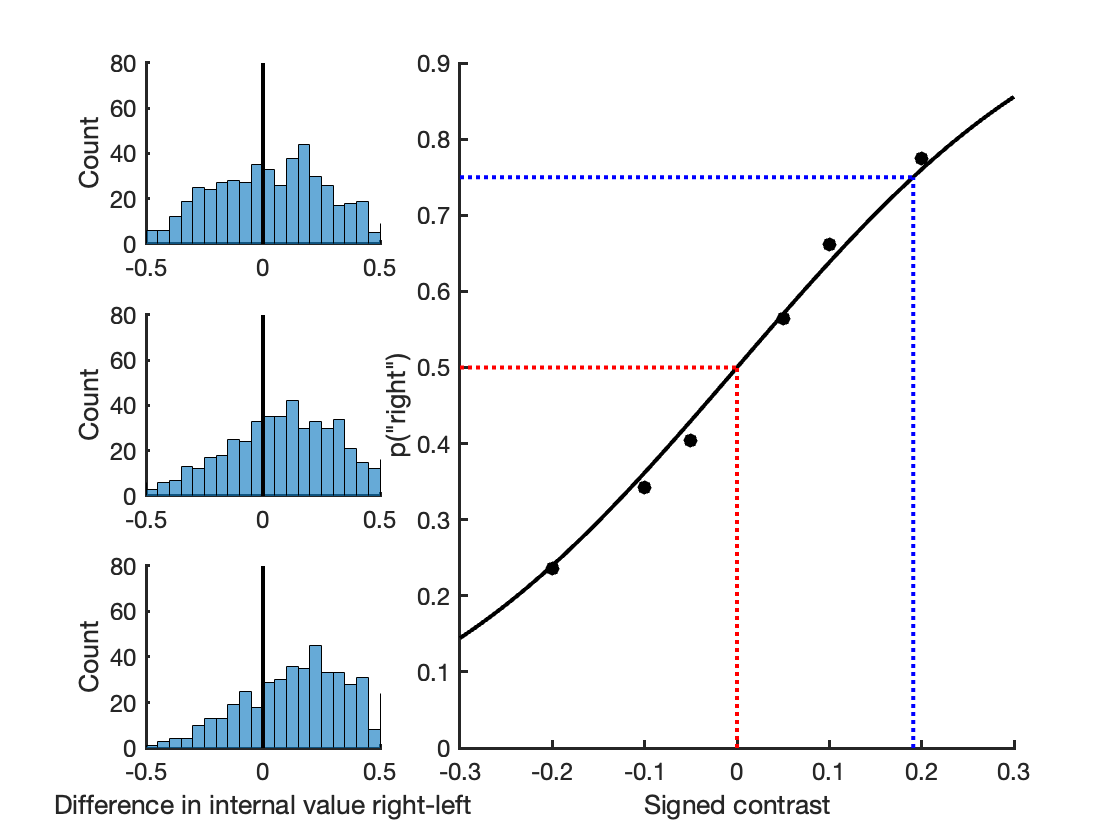


% The contrast varies on each trial:
signal_strengths = [0.05, 0.1, 0.2];
nsignals = length(signal_strengths);

% It is added on a background of noise:
noise_mean = 0;
noise_sd = 0.2;

ntrials = 1000; % 1000 trials per signal strength
pleft = 0.5;

% sample some noise
left_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;
right_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;

% loop to add signal
for si = 1:nsignals
    
    % half the time it's on the left, half the time on the right
    left_samps(1:round(ntrials*pleft),si) = left_samps(1:round(ntrials*pleft),si) + signal_strengths(si);
    right_samps(round(ntrials*pleft)+1:ntrials,si) = right_samps(round(ntrials*pleft)+1:ntrials,si) + signal_strengths(si);
     
end

% the observer responds "right" when the internal value is greater on the
% right
internal_val = right_samps - left_samps;
responses = internal_val>0;

% the proportion of "right" responses, for left and right signal trials
% separately
pright = nan(nsignals,2);


for si = 1:nsignals
    
    pright(si,1) = mean(responses(1:round(ntrials*pleft),si));
    pright(si,2) = mean(responses(round(ntrials*pleft)+1:ntrials,si));
    
    
end

% plot
figure;
% histograms of the evidence

for si = 1:nsignals
    
    subplot(3,3,(si*3)-2)
    hold on
    
    %histogram(internal_val(1:round(ntrials*pleft),si),'BinWidth',0.05)
    histogram(internal_val(round(ntrials*pleft)+1:ntrials,si),'BinWidth',0.05)
    plot([0,0],[0,80],'k','LineWidth',2)
    axis([-0.5,0.5,0,inf])
    ylabel('Count')
    makeMyPlotPretty
end

xlabel('Difference in internal value right-left')


subplot(3,3,[2,3,5,6,8,9])
hold on
scatter(signal_strengths*-1,pright(:,1),50,'k','filled')
scatter(signal_strengths,pright(:,2),50,'k','filled')
% the theoretical function
xs = linspace(-0.3,0.3,100);
ys = normcdf(xs,0,noise_sd*sqrt(2));
plot(xs,ys,'k','LineWidth',2)
plot([0,0],[0,0.5],'r:','LineWidth',2)
plot([-0.3,0],[0.5,0.5],'r:','LineWidth',2)
threshold = norminv(0.75,0,noise_sd*sqrt(2));
plot([threshold,threshold],[0,0.75],'b:','LineWidth',2)
plot([-0.3,threshold],[0.75,0.75],'b:','LineWidth',2)
xlabel('Signed contrast')
ylabel('p("right")')
makeMyPlotPretty

As the signal strength (contrast) increases, there is a greater difference in the internal value for the left vs right, and the proportion of "right" responses becomes more accurate (plotted on the left).

What we have plotted on the right is the psychometric function, which maps the proportion of responses against the external value: the contrast of the Gabor (signed by whether it was presented on the left or the right).

The theoretical description of the proportion of "right" responses is the cumulative gaussian. The mean of the gaussian is 0, the criterion for responding "right". The standard deviation reflects the noise causing the variability in the internal value, in this case the standard deviation of the noise multiplied by root-2 (because of the 2AFC design).

The properties of the gaussian can be inferred from the data. This is normally done using a procedure to find the values of the mean and standard deviation that best fit the data. Intuitively, the mean is the point on the x-axis where the line reaches 0.5 on the y-axis (red dotted line). The standard deviation reflects the slope of the line (we will examine this further below).

Another property people like to discuss is the 'threshold'. This is different from the 'threshold's we were talking about last week, from threshold theory. In this case, the threshold is the point on the x-axis where the line reaches 0.75 on the y-axis (or 0.5, or 0.816, or some other value, depending on the situation and who you are speaking to). The threshold is not supposed to be some special value, below which the psychological experience is categorically different (as in threshold theory). The threshold is an intuitive way of summarising the curve across participants. You might present the same stimuli to all participants, but their psychometric functions differ. Rather than comparing the proportion of "right" responses across all stimuli, you can compare a common value: what stimulus strength would have given 75% correct (blue dotted line).

**TASK 1:** Try changing the noise_sd parameter. What happens to the shape of the psychometric function? What happens to the threshold?

**TAKE-AWAY:** The threshold value is related to the slope of the psychometric function and can be used to summarise performance across stimulus strength values.

### c. The psychometric function for discrimination and identification

The same principles can be applied to the tasks of discrimination and identification. The key principle is that the psychological experience of any stimulus property is also disrupted by noise. Perhaps this is less intuitive than thinking of a signal added to a background of noise, but the principle is the same: neurons have probabilitstic firing rates, meaning their response to a stimulus may vary from one presentation to another. Take the Gabor example, a Gabor with a genuinely vertical orientation could be perceived as oriented slightly rightward (when briefly presented). On this occaision, neurons who like to respond to vertical things happened to fire less than they should and/or neurons who like rightward oriented things happened to fire more than they should and/or neurons who like to respond to leftward things happened to fire less than they should. 

So an observer making a judgement about some property of a clearly visible stimulus has the same problem as an observer trying ot detect a weak stimulus: their psychological experience is variable, so they must make an inference about the external cause.

**A side note on discrimination and identification...**

These tasks require the observer to make some categorical assessment of their psychological experience of a stimulus. I've grouped them together here because the terms are generally mixed up in the literature anyway.

What Christian Lorenzi describes in the lecture is the strict definintion of the discrimination task, where an observer is presented with two stimuli and asked if they are the same or different (or more broadly, do they come from the same category). This seems like a 2AFC task because there are two stimuli presented, but actually, the observer only has one piece of evidence on which to make their decision from the two stimuli - their similarity. The observer still has to set a criterion on which to decide whether the two stimuli are different enough to respond 'different' (or similar enough to respond 'same'). The psychometric function would look similar to the yes/no detection task above: there is a zero-value where there is no difference, and then increasing difference. A 2AFC version would actually be a task in which the observer is presented with two pairs of stimuli and asked which pair is 'more different'. This would generate the psychometric function 

Often we use the term 'discrimination' for tasks that are more strictly 'identification'. This is especially in tasks where the categorical assessment is around some 'natural' boundary on a continuous scale. For example, the orientation of the Gabor: we can ask participants if the orientation is tilted more left or right of vertical, there are varying degrees of tilt (a continuous scale), and vertical is a kind of natural boundary, a concept that can be can easily compared with the experience of the presented stimulus without the experiementer also showing a vertical stimulus on each trial. We like to call this 'orientation discrimination', because in a sense you are making a comparison (with your natural sense of vertical), but really it's identification because the task is to identify whether the stimulus orientation belongs to the category 'leftward tilted' or 'rightward tilted'.

**Back to psychometric functions...**

Let's simulate an observer who is asked to decide if a Gabor is tilted more leftward or rightward of vertical

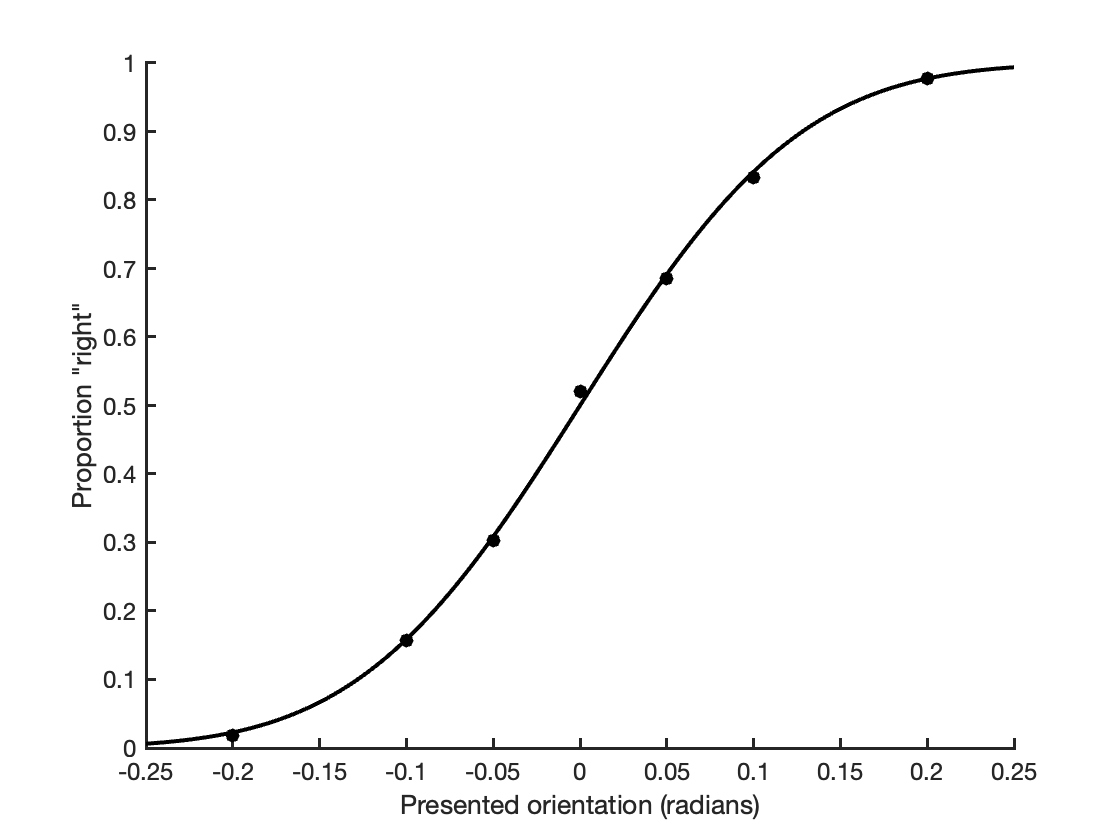


% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
% here, negative is leftward. I've deliberately kept the values the same as
% above for contrast for the sake of demonstration. If you're unhappy about
% this imagine it's in radians (ranging from ~3 to ~11 degrees tilt) it's
% more realistic

nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate lots of trials
ntrials = 1000; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;

% the observer compares the internal value to their representation of
% vertical
criterion = 0;

proportion_right = mean(samples > criterion,1); % the average  over trials

% plot
figure;
hold on
scatter(signal_strengths,proportion_right,50,'k','filled')
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ys = normcdf(xs,criterion,noise_sd);
plot(xs,ys,'k','LineWidth',2)
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

This psychometric function looks like the one from the 2AFC detection task in that it ranges from 0 to 1, but notice the slope is different. In the 2AFC task the root-2 correction is applied because there are two independent stimuli presented, here there is only one. This is essentially a yes/no task, the observer is deciding 'yes it is rightward' or 'no it is not rightward' (it is leftward).

All three of the psychometric functions we have seen have cumulative gaussian/normal theoretical distributions, they differ in the assumed standard deviation of that distribution, and the range of values possible.

**TAKE-AWAY:** we can make similar predictions about the shape of the psychometric function across different tasks.

### d. Slope, threshold, and bias

The properties of the psychometric function help us to quantify different relations between the internal value and the external stimulus.

The slope tells us about the noise affecting the precision of the interal value (its variability).

Simulation example with Gabor orientation:

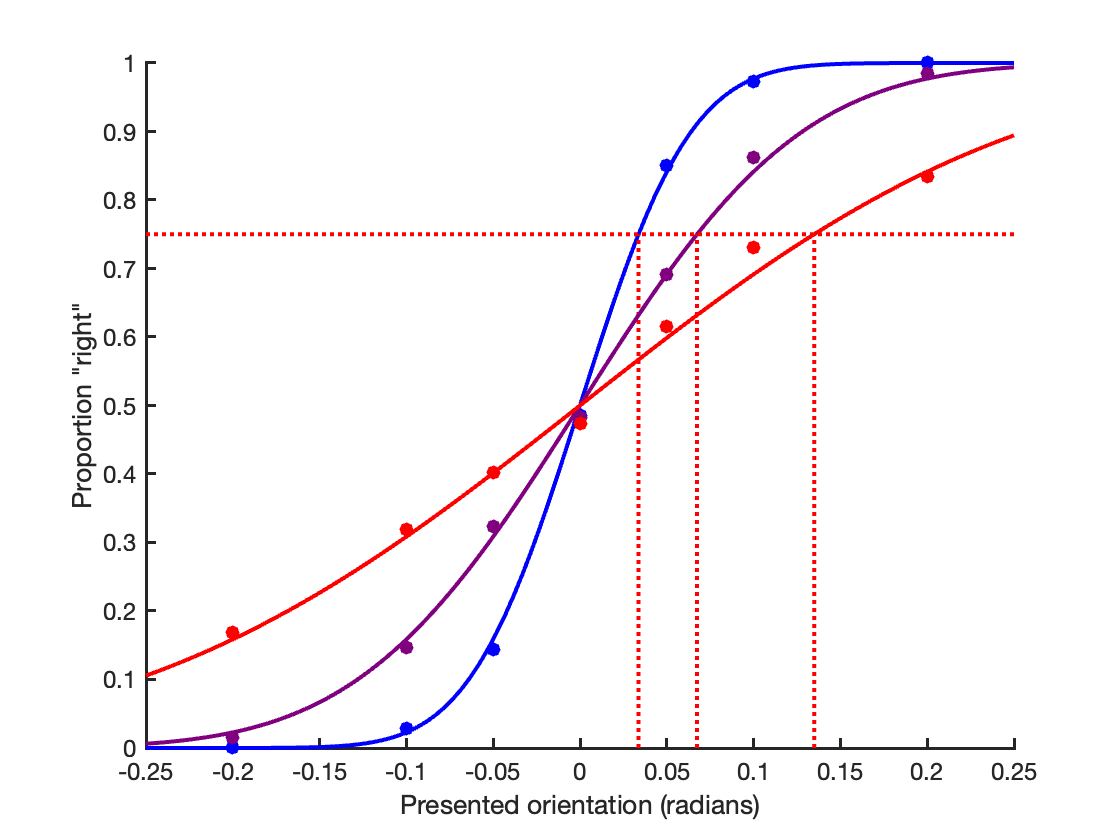


% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
% here, negative is leftward. I've deliberately kept the values the same as
% above for contrast for the sake of demonstration. If you're unhappy about
% this imagine it's in radians (ranging from ~3 to ~11 degrees tilt) it's
% more realistic

nsignals = length(signal_strengths);

% the observer compares the internal value to their representation of
% vertical
criterion = 0;

% simulate lots of trials
ntrials = 1000; % per signal strength

% the signal is added to noise
noise_sds = [0.05,0.1,0.2];
nsds = length(noise_sds);

% pre-allocate
proportion_right = nan(nsignals,nsds);

% loop
for ni = 1:nsds

    % samples of internal values which the observer experiences (signal+noise)
    samples = ( randn(ntrials,nsignals)*noise_sds(ni) ) + signal_strengths;
    proportion_right(:,ni) = mean(samples > criterion,1); % the average  over trials

end

% plot
% for the theoretical psychometric function
xs = linspace(-0.25,0.25,100);

% colours for the noise sds
mycolours = [linspace(0,1,nsds)',zeros(nsds,1),linspace(1,0,nsds)'];

figure;
hold on
for ni = 1:nsds
    scatter(signal_strengths,proportion_right(:,ni),50,mycolours(ni,:),'filled')

    ys = normcdf(xs,criterion,noise_sds(ni));
    plot(xs,ys,'Color', mycolours(ni,:),'LineWidth',2)
    
    threshold = norminv(0.75,criterion,noise_sds(ni));
    plot([threshold,threshold],[0,0.75],'r:','LineWidth',2)
end
plot([-0.25,0.25],[0.75,0.75],'r:','LineWidth',2)
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

Increasing the noise decreases the slope (it is flatter) because the observer experiences more variability across multiple presentations of the same external stimulus. This corresponds to a larger threshold: more tilt is required to obtain 75% correct.

BUT WAIT! That isn't 75% correct, it's 75% responding 'right'!

It's also 75% correct because the observer is not biased.

There are probably better examples to demonstrate this, but imagine an observer who has a skewed idea of what vertical is...

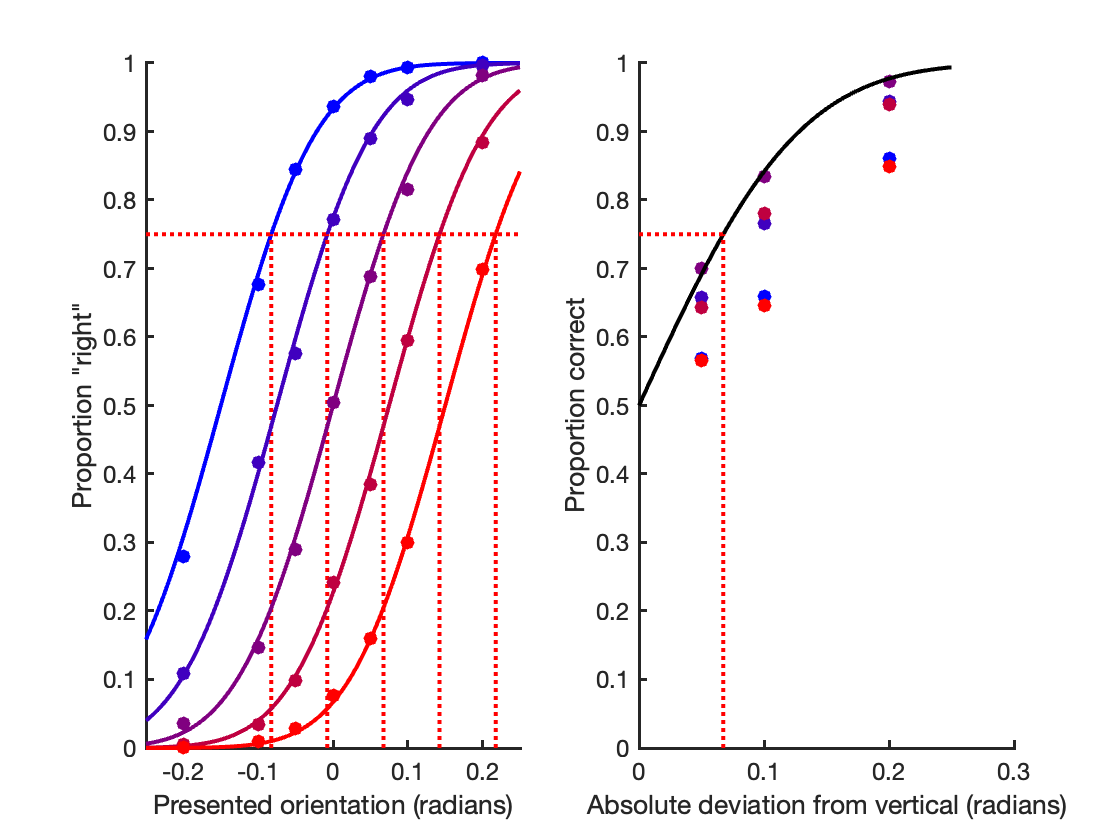


% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate lots of trials
ntrials = 1000; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;

% the observer compares the internal value to a criterion
% compare different criteria
ncriteria = 5;
criteria = linspace(-0.15,0.15,ncriteria);

% pre-allocate
proportion_right = nan(nsignals,ncriteria);

% loop to calculate the proportion of 'yes' responses
for ci = 1:ncriteria
    
    proportion_right(:,ci) = mean(samples > criteria(ci),1); % the average  over trials
    
end

% plot
% for the theoretical psychometric function
xs = linspace(-0.25,0.25,100);

% colours for the criteria
mycolours = [linspace(0,1,ncriteria)',zeros(ncriteria,1),linspace(1,0,ncriteria)'];

figure;
subplot(1,2,1)
hold on
for ni = 1:ncriteria
    scatter(signal_strengths,proportion_right(:,ni),50,mycolours(ni,:),'filled')

    ys = normcdf(xs,criteria(ni),noise_sd);
    plot(xs,ys,'Color', mycolours(ni,:),'LineWidth',2)
    
    badthreshold = norminv(0.75,criteria(ni),noise_sd);
    plot([badthreshold,badthreshold],[0,0.75],'r:','LineWidth',2)
end
plot([-0.25,0.25],[0.75,0.75],'r:','LineWidth',2)
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

% calculate proportion correct by orientation deviation
pcorrect = nan(floor(nsignals/2),ncriteria); % ignore vertical orientation

for si = 1:floor(nsignals/2)
    pcorrect(si,:) = ( (1-proportion_right(round(nsignals/2)-si,:)) + proportion_right(si+round(nsignals/2),:) )./2;
end

% plot
subplot(1,2,2)

hold on
for ci = 1:ncriteria
    
    scatter(signal_strengths(round(nsignals/2)+1:nsignals),pcorrect(:,ci),50,mycolours(ci,:),'filled')
    
end

% theoretical distribution
xs = linspace(0,0.25,100);
ys = normcdf(xs,0,noise_sd);
plot(xs,ys,'k','LineWidth',2)

% real threshold
threshold = norminv(0.75,0,noise_sd);
plot([0,threshold],[0.75,0.75],'r:','LineWidth',2);
plot([threshold,threshold],[0,0.75],'r:','LineWidth',2)
xlabel('Absolute deviation from vertical (radians)')
ylabel('Proportion correct')
makeMyPlotPretty

On the left, you see the psychometric functions shift with bias, while the slope remains the same. Similar to last week, this shift with bias is attributed to the criterion. This shift with bias could be due to a skewed idea of what is vertical (the observer genuinely perceives the Gabors as oriented more leftward or rightward on average than they are), it could be due to some strategy (for example, if the observer were given a greater reward for correct 'right' responses than 'left responses'), or Morgan et al. (2012) showed observers can voluntarily shift their criterion in this way by instruction alone, without affecting the slope (one could imagine if someone tried to place their criterion unnaturally, this could introduce another source of noise, where the criterion could jitter about from trial to trial, this idea is offered as a potential explanation of Blindsight: Azzopardi & Cowey, 2001).

On the right, proportion correct is scattered for each criterion (colours) against the theoretical proportion correct for an unbiased observer. While a little bit of bias is fine, more extreme bias affects our measure of proportion correct (just as we saw last week with simple detection designs). This can be problematic for using staircase procedures (we will discuss this later) to estimate a threshold: many procedures use a form of step, where the stimulus value is made more difficult or easier according to the number of consecutive correct and incorrect responses. 

**TAKE-AWAY: **While the threshold is proposed to be a proxy for sensitivity, it can also be affected by bias, especially in subjective tasks.

### e. Measuring psychometric functions

So far, we have been simulating an observer performing thousands of trials. With human participants we are often constrained to many fewer trials. How many trials do we need to get a good measure?

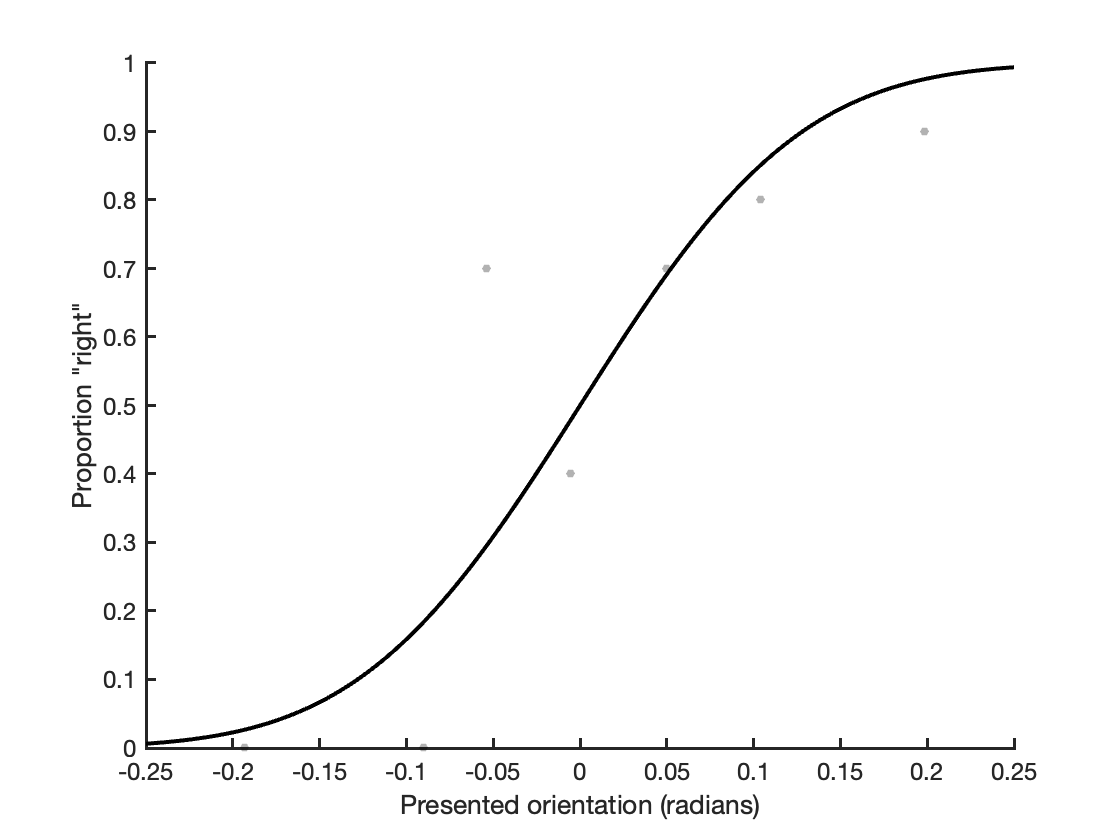

% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate a few trials
ntrials = 10; % per signal strength

% do this a few times
nsimulations = 1;

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals,nsimulations)*noise_sd ) + signal_strengths;

% the observer compares the internal value to a criterion
criterion = 0;

proportion_right = squeeze(mean(samples > criterion,1)); % the average  over trials

% plot
% spread out the simulations a bit to get a good look
xjitter = repmat(signal_strengths',1,nsimulations)+unifrnd(-0.01,0.01,nsignals,nsimulations);

figure
hold on
% plot the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ys = normcdf(xs,0,noise_sd);
plot(xs,ys,'k','LineWidth',2)
% scatter the measures
scatter(xjitter(:),proportion_right(:),20,'k','filled','MarkerFaceAlpha',0.3)
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

Why are the values so spread out along the y-axis?

**TASK 2:** change the number of trials, and see what happens

We have also thus far been working with a psychometric function that is known to us, we can plot the theoretical function because we know the criterion and the noise affecting the simulated responses. But in the real world, we are interested in finding these values based on the participants' responses. 

Finding the values is not so trivial. What we do is use a technique to search through different values of criterion and slope until we find the values that 'best fit' the data. By 'best fit' what we mean is minimise some measure of the error between the data and the prediction from the theoretical distribution. One measure of the error is the squared distance (of the data point from the prediction). A better measure of the error of psychometric functions is the negative log likelihood: this examines the probability of the data point given the theoretical prediction and the number of trials. Conceptually this can be seen as using the spread we see above in the observed data to estimate how likely it was that the observer would achieve that proportion of responses. We take the log, so that we can simply add the likelihoods across data points (rather than multiply), and the negative, because we still want to minimise (because that's what the algorithm does).

How does this work in Matlab?

% simulate an observer and fit the psychometric function
% The orientation varies on each trial:
signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate a few trials
ntrials = 10; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;

% the observer compares the internal value to a criterion
criterion = 0;
responses = samples > criterion;
proportion_right = mean(responses,1); % the average  over trials

% define the psychometric function function
probitPF = @(p,x) normcdf(x,p(1),p(2)); % this is a one-line function in matlab
% I've called it 'probit' because that is a term for the inverse cumulative
% gaussian
% p is the parameters - we are fitting 2 parameters, the mean and the
% standard deviation
% x is the stimulus strength

% I've defined another function at the end of this script, which calculates
% the negative log likelihood
% The function takes as input the parameters, the psychometric function
% handle, the stimulus values, and the count of responses for left and
% right for each stimulus value
respCounts = [proportion_right*ntrials;(1-proportion_right)*ntrials];

% to find the best fitting parameters, we use another function from matlab,
% which minimises the negative loglikelihood

[paramsBest,nll] = fminsearch(@(p) negLogLik(p,probitPF,signal_strengths,respCounts),[criterion,noise_sd])

paramsBest =     0.0225    0.1019


nll = 30.6164

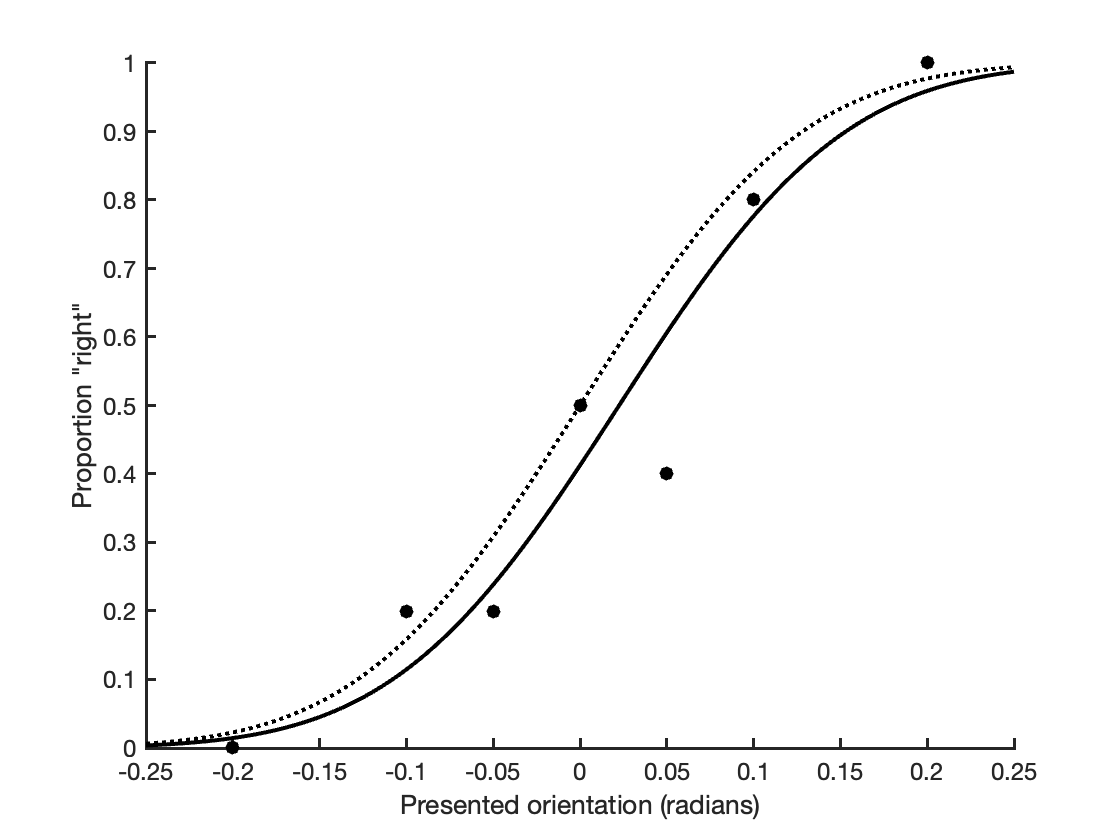

% here I've cheated a bit and used as a starting point for the search, the
% actual parameters that define the true psychometric function

% plot
figure
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = normcdf(xs,criterion,noise_sd);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = normcdf(xs,paramsBest(1),paramsBest(2));
plot(xs,ysFit,'k','LineWidth',2)

% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

Because we have few trials, there is some difference between the 'true' psychometric function and the one from the best fitting parameters.

**TASK 3: **Run the section a few times, check the difference between the fit and the ground truth, see what happens when you increase the number of trials

The 'probit' cumulative gaussian is not the only form of psychometric function.

Another popular choice is the logistic function. The shape is pretty similar, but the theoretical basis is different. The logistic function assumes responses are drawn from a binomial distribution. We can motivate using a logistic for theoretical reasons in some contexts. Another motivation is practical. The logistic function can be used in general linear models, so it's easier to fit, can be compared with other variables, and can also be fit in combination with other variables.

% logistic psychometric function (p(theta,sigma)):
logisticPF = @(p,x) (1./(1+exp(-1*(p(2)).*(x-p(1)))));

% use glmfit to fit the psychometric function
b = glmfit(signal_strengths',[respCounts(1,:)', sum(respCounts,1)'],'binomial','link','logit');
% Note: when using glmfit, do not add the constant.

% Parameters: theta = -b(1)/b(2)
paramsBest2 = [-b(1)/b(2) b(2)];

% calculate the negative log likelihood
nll2 = negLogLik(paramsBest2,logisticPF,signal_strengths,respCounts)

nll2 = 30.8463


% plot
figure
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = normcdf(xs,criterion,noise_sd);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = normcdf(xs,paramsBest(1),paramsBest(2));
plot(xs,ysFit,'k','LineWidth',2)

% the logistic psychometric function
ysFit2 = logisticPF(paramsBest2,xs);
plot(xs,ysFit2,'r:','LineWidth',2)

% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

You should see that practically, there is little difference between the two psychometric functions. The probit should fit slightly better than the logit in terms of negative log likelihood, this is because the probit is the generating function we simulated behaviour from.

**TAKE-AWAY: **To get a good estimate of the psychometric function, the more trials the better. While the probit matches the theoretical assumptions in this case, the logit is often practical and produces similar results.

### f. Lapses and wobbly criteria

So far, we have been assuming that our observer always responds based on their internal value and the same stable criterion.

The term lapse was introduced to describe trials where an observer has a lapse of attention, for some reason they didn't properly process the signal, or they accidentally pressed the wrong button. Lapses are most clearly seen at the extremes of the function, where an observer should achieve 100% correct, but doesn't.

Lapses interrupt our ability to get a good measure of the mean and standard deviation of the psychometric function.

Let's have a look

signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate lots of trials
ntrials = 1000; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;
criterion = 0;

lapse_rate = 0.1;
% this means that on 10% of trials, the observer makes a random response

responses = samples > 0;

% replace the response with a random one on 10% of trials
responses(randi(nsignals*ntrials,1,round(nsignals*ntrials*lapse_rate))) = randi(2,1,round(nsignals*ntrials*lapse_rate))-1;

% proportions and counts
proportion_right = mean(responses,1); % the average  over trials
respCounts = [proportion_right*ntrials;(1-proportion_right)*ntrials];

% fit the psychometric function
[paramsBest,nll] = fminsearch(@(p) negLogLik(p,probitPF,signal_strengths,respCounts),[criterion,noise_sd])

% plot
figure
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = (normcdf(xs,criterion,noise_sd).*(1-lapse_rate))+(lapse_rate/2);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = normcdf(xs,paramsBest(1),paramsBest(2));
plot(xs,ysFit,'k','LineWidth',2)
% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

Because we haven't accounted for the lapse rate in our parametric fit, we end up estimating more noise than what was actually there.

We can fit another parameter to estimate the lapse rate, but this requires a lot of trials.

probitPFLapse = @(p,x) (normcdf(x,p(1),p(2)).*(1-p(3)))+(p(3)/2);

% fit the psychometric function
[paramsBestLapse,nllLapse] = fminsearch(@(p) negLogLik(p,probitPFLapse,signal_strengths,respCounts),[criterion,noise_sd,lapse_rate])

% plot
figure;
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = (normcdf(xs,criterion,noise_sd).*(1-lapse_rate))+(lapse_rate/2);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = probitPFLapse(paramsBestLapse,xs);
plot(xs,ysFit,'r:','LineWidth',2)
% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty
% what would have happened if we only had 30 trials?
ntrials = 30;
responses = responses(1:ntrials,:);

% proportions and counts
proportion_right = mean(responses,1); % the average  over trials
respCounts = [proportion_right*ntrials;(1-proportion_right)*ntrials];

% fit lapse model again
[paramsBestLapse,nllLapse] = fminsearch(@(p) negLogLik(p,probitPFLapse,signal_strengths,respCounts),[criterion,noise_sd,lapse_rate])

% plot
figure;
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = (normcdf(xs,criterion,noise_sd).*(1-lapse_rate))+(lapse_rate/2);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = probitPFLapse(paramsBestLapse,xs);
plot(xs,ysFit,'r:','LineWidth',2)
% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

It's easy for the psychometric function fit to be biased by the extremes, such that with a small number of trials the lapse rate parameter can really bias the measure.

What about the stable criterion assumption? Lets say that, from trial to trial the observer moves their criterion around randomly. As if their internal representation of what is vertical can shift slightly, or is noisy itself.

signal_strengths = [-0.2,-0.1,-0.05,0, 0.05,0.1, 0.2];
nsignals = length(signal_strengths);

% the signal is added to noise
noise_sd = 0.1;

% simulate lots of trials
ntrials = 1000; % per signal strength

% samples of internal values which the observer experiences (signal+noise)
samples = ( randn(ntrials,nsignals)*noise_sd ) + signal_strengths;
criterion = randn(size(samples))*0.05;

responses = samples > criterion;

% proportions and counts
proportion_right = mean(responses,1); % the average  over trials
respCounts = [proportion_right*ntrials;(1-proportion_right)*ntrials];

% fit the psychometric function
[paramsBest,nll] = fminsearch(@(p) negLogLik(p,probitPF,signal_strengths,respCounts),[0,noise_sd])

% plot
figure;
hold on
% the theoretical psychometric function
xs = linspace(-0.25,0.25,100);
ysTrue = normcdf(xs,0,noise_sd);
plot(xs,ysTrue,'k:','LineWidth',2)

% the calculated psychometric function
ysFit = probitPF(paramsBest,xs);
plot(xs,ysFit,'r:','LineWidth',2)
% the data
scatter(signal_strengths,proportion_right,50,'ko','filled')
xlabel('Presented orientation (radians)')
ylabel('Proportion "right"')
makeMyPlotPretty

The slope of the psychometric function is underestimated again. This time there is nothing we can do about it (or perhaps, we could examine sequential dependencies in responses; Treisman & Williams, 1984; Azzopardi & Cowey, 2001; Vloeberghs et al., 2024).

**TAKE-AWAY: **Lapses and wobbly criteria make it look like the observer has a noisier internal value of the stimulus property than they really do.

### g. Linear scales and equal variance

While measuring the psychometric function tells us about an observer's response criterion and the noise affecting their internal value associated with the stimulus, another important aspect of the function is how the data might systematically deviate from it. This can happen because the internal continuum of the observer does not vary linearly with the stimulus property presented (linear scale), or because the noise affecting the internal value is not equal across stimulus values (equal variance). 

The first issue is fairly common, and the fix is straight forward. Above, we have been plotting the proportion of rightward responses against the presented orientation, and simulating an observer whose internal value of orientation varies linearly with the presented orientation. But what about other stimulus properties? The contrast of the Gabor is another property commonly manipulated. The contrast describes the scale of the black-to-white sinusoidal pattern: A contrast of 1 describes going from absolute black to absolute white (or the maximum achieved by the presentation monitor), whereas a contrast of 0.5 describes going from half-black to half-white. In the detection experiment simulated in section b above, we assumed a linear relationship between the presented contrast and the internal value (or, perceived contrast). It turns out this isn't a great assumption. Perceived contrast actually operates as a power function of presented contrast (Gottesman, Rubin, & Legge, 1981). This is true of many perceptual magnitudes, which we will be exploring more in depth next week.

A conceptual example (which may or may not help). Imagine you are shown a very dim light, so dim you barely perceive it. A slightly less dim light is probably much more visible. If the luminance of the light were doubled, this would probably make a big difference to your perception of brightness. Now image a bright light, a lightbulb, and then imagine that doubled. It does go from very bright, to very very bright, but this might not feel the same as something barely visible turning to clearly visible. Maybe that doesn't help. You can play with the contrast of the Gabor in section a above if that helps.

What does it look like if perceived contrast follows a power law, but we plot responses against the presented contrast?

% The contrast varies on each trial:
signal_strengths = [0.025, 0.05, 0.1, 0.2];
nsignals = length(signal_strengths);

% internal strength is a power of 0.7
internal_strength = signal_strengths.^0.7;

% It is added on a background of noise:
noise_mean = 0;
noise_sd = 0.1;

ntrials = 1000; % 1000 trials per signal strength
pleft = 0.5;

% sample some noise
left_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;
right_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;

% loop to add signal (internal value)
for si = 1:nsignals
    
    % half the time it's on the left, half the time on the right
    left_samps(1:round(ntrials*pleft),si) = left_samps(1:round(ntrials*pleft),si) + internal_strength(si);
    right_samps(round(ntrials*pleft)+1:ntrials,si) = right_samps(round(ntrials*pleft)+1:ntrials,si) + internal_strength(si);
     
end

% the observer responds "right" when the internal value is greater on the
% right
internal_val = right_samps - left_samps;
responses = internal_val>0;

% the proportion of "right" responses, for left and right signal trials
% separately
pright = nan(nsignals,2);


for si = 1:nsignals
    
    pright(si,1) = mean(responses(1:round(ntrials*pleft),si));
    pright(si,2) = mean(responses(round(ntrials*pleft)+1:ntrials,si));
    
    
end

% fit a psychometric function
% proportions and counts
proportion_right = [pright(:,1);pright(:,2)]'; % the average  over trials
respCounts = [proportion_right*ntrials*pleft;(1-proportion_right)*ntrials*pleft];

% fit the psychometric function
[paramsBest,nll] = fminsearch(@(p) negLogLik(p,probitPF,[-signal_strengths,signal_strengths],respCounts),[0,noise_sd])


% plot
figure;

hold on
scatter(signal_strengths*-1,pright(:,1),50,'k','filled')
scatter(signal_strengths,pright(:,2),50,'k','filled')
% the theoretical function
xs = linspace(-0.3,0.3,100);
ys = normcdf(xs,0,noise_sd*sqrt(2));
plot(xs,ys,'k','LineWidth',2)
ys2 = probitPF(paramsBest,xs);
plot(xs,ys2,'r:','LineWidth',2)

xlabel('Signed contrast')
ylabel('p("right")')
makeMyPlotPretty

figure;
hold on
scatter(internal_strength*-1,pright(:,1),50,'k','filled')
scatter(internal_strength,pright(:,2),50,'k','filled')
% the theoretical function
xs = linspace(-0.3,0.3,100);
ys = normcdf(xs,0,noise_sd*sqrt(2));
plot(xs,ys,'k','LineWidth',2)

xlabel('Internal value')
ylabel('p("right")')
makeMyPlotPretty

You should see two things. First, the old theoretical distribution (solid black line on first of the two plots) is completely inappropriate. This is because the internal value is actually stronger than what we would assume from a linear relationship. Second, even the best fitting psychometric function (red dashed line on first of the two plots) doesn't match the data well (especially for contrast close to 0). This is because of the non-linear scaling. When we plot as a function of the internal value (second plot) things line up just as well as before. Often we don't know the internal value. We could add a scaling parameter assuming a power law, or, if this is what we are really interested in, we should use a method to estimate it directly (which we will discuss next week).

The second issue, the equal vairance assumption (which you may have encountered if you went through the optional extras from last week), also has a strong theoretical basis. The model of Lu and Dosher (1998), for example, includes 'multiplicative noise', where the variance of the noise term scales with the magnitude of the stimulus. This creates a similar problem for the psychometric function

% The contrast varies on each trial:
signal_strengths = [0.025, 0.05, 0.1, 0.2];
nsignals = length(signal_strengths);


% It is added on a background of noise:
noise_mean = 0;

% The variance increases with increasing signal
noise_sd = 0.07.*sqrt(signal_strengths./0.2);

ntrials = 1000; % 1000 trials per signal strength
pleft = 0.5;

% sample some noise
left_samps = ( randn(ntrials,nsignals).*noise_sd ) + noise_mean;
right_samps = ( randn(ntrials,nsignals).*noise_sd ) + noise_mean;

% loop to add signal (internal value)
for si = 1:nsignals
    
    % half the time it's on the left, half the time on the right
    left_samps(1:round(ntrials*pleft),si) = left_samps(1:round(ntrials*pleft),si) + signal_strengths(si);
    right_samps(round(ntrials*pleft)+1:ntrials,si) = right_samps(round(ntrials*pleft)+1:ntrials,si) + signal_strengths(si);
     
end

% the observer responds "right" when the internal value is greater on the
% right
internal_val = right_samps - left_samps;
responses = internal_val>0;

% the proportion of "right" responses, for left and right signal trials
% separately
pright = nan(nsignals,2);


for si = 1:nsignals
    
    pright(si,1) = mean(responses(1:round(ntrials*pleft),si));
    pright(si,2) = mean(responses(round(ntrials*pleft)+1:ntrials,si));
    
end

% fit a psychometric function
% proportions and counts
proportion_right = [pright(:,1);pright(:,2)]'; % the average  over trials
respCounts = [proportion_right*ntrials*pleft;(1-proportion_right)*ntrials*pleft];

% fit the psychometric function
[paramsBest,nll] = fminsearch(@(p) negLogLik(p,probitPF,[-signal_strengths,signal_strengths],respCounts),[0,noise_sd(end)])


% plot
figure;
hold on
scatter(signal_strengths*-1,pright(:,1),50,'k','filled')
scatter(signal_strengths,pright(:,2),50,'k','filled')
% the theoretical function
xs = linspace(-0.3,0.3,100);
ys = normcdf(xs,0,noise_sd(end));
plot(xs,ys,'k','LineWidth',2)
ys2 = probitPF(paramsBest,xs);
plot(xs,ys2,'r:','LineWidth',2)

xlabel('Signed contrast')
ylabel('p("right")')
makeMyPlotPretty

You should see a similar problem to before: the data points are displaced even from the best fitting parameters.

You may notice this problem drives the data in a similar direction to the problem of non-linear scaling of the internal variable. Here the difference between the psychometric function and the data tells us that something is off (we have the wrong scale, or unequal variance), but again, if this is something we are interested in understanding, a different method would be appropriate. Magnitude estimation is best for understanding how the internal value scales with the external stimulus (more next week); external noise manipulations are best for understanding multiplicative noise (as in Lu and Dosher, 1998, but see also this fun argument: Gorea & Sagi, 2001 vs. Kontsevich et al., 2002, and the final blow, Zak et al., 2012).

Another consideration is the number of trials. Here we have simulated 1000 trials per stimulus value, and we see a consistent pattern of deviation from the prediction of the psychometric function. Often in human experiements we have far fewer trials, and so the deviation will be masked by the estimation error we simulated in section e above. The deviations are pretty common in animal data, where many trials make it stand out (one example: Hermoso-Mendizabal et al., 2020), this is not normally a problem for the overall results of a paper.

**TAKE-AWAY:** Data can systematically deviate from the predictions of the psychometric function, which is visible if many trials are collected. These deviations are interesting, but the underlying cause is better tested with other methods.

## Optional Extras

### h. Cool "double-knob" designs

You don't have to limit yourself to asking observers one question about what they perceived. You can ask 2! (or more... we went a bit extreme here: Recht et al., 2022)

In double-judgement psychophysics, or "double-knob" tasks (Klein, 1985), the participant is presented with a stimulus (often in a 2-interval design) and asked to make two reports about what they perceived. For example, detect the interval the stimulus was presented in, and identify its colour. Rollman, & Nachmias (1972) presented observers with either a faint 'chromatic flash' (coloured light), or nothing, each trial and asked participants if they detected the stimulus and whether it was red or green. They found identification (red vs green) performance was better than chance even on trials where the observer reported not detecting the stimulus. Spooky.

Because they used a yes/no detection task, maybe you could argue that observers were just conservative in reporting 'yes' to detecting the flash, rather their performance on the red vs green identification task shows they had some ("conscious") detection experience of the stimulus.

Another example, Allik and colleagues (1982; 2014; the experiment was so good they did it twice!) presented participants with two 'bullseye' images (a circle with a dot in it). In one image the dot was offset from the centre of the circle slightly left or right, in the other it was centred. Participants were asked to perform a (2AFC) detection of the offset, and discriminate whether the offset was left or right of vertical. Discrimination performance (left vs right) was better than chance even on trials where the observer could not detect the offset. This seems kind of less spooky, but it's the same idea as above.

When you simulate the experiment, everything makes sense.

% The dot offset varies on each trial:
signal_strengths = [-0.3, -0.2, -0.1, -0.05, -0.025, 0.025, 0.05, 0.1, 0.2, 0.3];
nsignals = length(signal_strengths);

% It is added on a background of noise:
noise_mean = 0;
noise_sd = 0.07;

ntrials = 1000; % 1000 trials per signal strength
pfirst = 0.5;

% sample some noise
first_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;
second_samps = ( randn(ntrials,nsignals)*noise_sd ) + noise_mean;

% loop to add signal
for si = 1:nsignals
    
    % half the time the second stimulus is deviated, half the time the first
    first_samps(1:round(ntrials*pfirst),si) = first_samps(1:round(ntrials*pfirst),si) + signal_strengths(si);
    second_samps(round(ntrials*pfirst)+1:ntrials,si) = second_samps(round(ntrials*pfirst)+1:ntrials,si) + signal_strengths(si);
     
end

% the observer responds "second" when the absolute deviation is greater on the
% second presentation
internal_val_detect = abs(second_samps) - abs(first_samps);
detect_responses = internal_val_detect > 0;

% the observer response "right" when the overall devation is more rightward
% (positive)
internal_val_identify = first_samps + second_samps;
identity_responses = internal_val_identify > 0;

% the proportion of responses, first and second interval presentations
% separately
psecond = nan(nsignals,2);
pright = nan(nsignals,2);


for si = 1:nsignals
    
    pright(si,1) = mean(identity_responses(1:round(ntrials*pfirst),si));
    pright(si,2) = mean(identity_responses(round(ntrials*pfirst)+1:ntrials,si));
    
    psecond(si,1) = mean(detect_responses(1:round(ntrials*pfirst),si));
    psecond(si,2) = mean(detect_responses(round(ntrials*pfirst)+1:ntrials,si));
    
    
end

% full psychometric
pright_full = mean(pright,2);
psecond_full = nan(nsignals,1);
psecond_full(1:(nsignals/2)) = psecond(1:(nsignals/2),1);
psecond_full((nsignals/2)+1:nsignals) = psecond((nsignals/2)+1:nsignals,2);


% proportion of correct responses, by absolute deviation
abs_dev = unique(abs(signal_strengths));
nad = length(abs_dev);


pcorrect_detect = nan(nad,1);
pcorrect_identity = nan(nad,1);

% this would not be correct if the stimuli were not presented in equal
% proportions of intervals (pfirst ~= 0.5)
for ai = 1:nad
    
    si = abs(signal_strengths) == abs_dev(ai);
    
    pcorrect_detect(ai) = mean(( psecond(si,2) + (1-psecond(si,1)) )/2);
    
    si1 = signal_strengths == -abs_dev(ai);
    si2 = signal_strengths == abs_dev(ai);
    pcorrect_identity(ai) = ( (1-pright_full(si1,1)) + pright_full(si2,1) )/2;
    
    
    
end

figure;
hold on
plot(abs_dev,pcorrect_identity,'b','LineWidth',2)
plot(abs_dev,pcorrect_detect,'r','LineWidth',2)
scatter(abs_dev,pcorrect_identity,100,'b','filled')
scatter(abs_dev,pcorrect_detect,100,'r','filled')
xlabel('absolute offset')
ylabel('proportion correct')
legend('Identification','detection','location','southeast')
makeMyPlotPretty

It really looks like observers can discriminate offsets that they cannot detect.


% fit and plot psychometric
% this time use logistic
respCounts_identify = [pright_full*ntrials*pfirst,(1-pright_full)*ntrials*pfirst];
respCounts_detect= [psecond_full*ntrials*pfirst,(1-psecond_full)*ntrials*pfirst];

% use glmfit to fit the psychometric function
b_d = glmfit(signal_strengths',round([respCounts_detect(:,1), sum(respCounts_detect,2)]),'binomial','link','logit');

b_i = glmfit(signal_strengths',round([respCounts_identify(:,1), sum(respCounts_identify,2)]),'binomial','link','logit');
% Note: when using glmfit, do not add the constant.

% Parameters: theta = -b(1)/b(2)
paramsBest_detect = [-b_d(1)/b_d(2) b_d(2)];
paramsBest_identify = [-b_i(1)/b_i(2) b_i(2)];

% logistic psychometric function (p(theta,sigma)):
logisticPF = @(p,x) (1./(1+exp(-1*(p(2)).*(x-p(1)))));

xs = linspace(-0.4,0.4,100);
ys_d = logisticPF(paramsBest_detect,xs);
ys_i = logisticPF(paramsBest_identify,xs);

% can you think why logistic might be theoretically more appropriate here?

figure;
hold on
plot(xs,ys_d,'r','LineWidth',2)
plot(xs,ys_i,'b','LineWidth',2)
scatter(signal_strengths,pright_full,100,'bo','filled')
scatter(signal_strengths,psecond_full,100,'ro','filled')
xlabel('Dot offset')
ylabel('Proportion "second"')
makeMyPlotPretty

The detection judgements don't look like they follow a psychometric function!

% plot the evidence, and visualise the decision rules
figure;
subplot(2,2,1)
hold on
% some colours
r1 = [0,0.2,0.8];
r2 = [0,0.8,0.2];
scatter(first_samps(identity_responses==1),second_samps(identity_responses==1),30,r1,'filled','MarkerFaceAlpha',0.15)
scatter(first_samps(identity_responses==0),second_samps(identity_responses==0),30,r2,'filled','MarkerFaceAlpha',0.15)
plot([-0.6,0.6],[0,0],'k','LineWidth',2)
plot([0,0],[-0.6,0.6],'k','LineWidth',2)
xlabel('Interval 1 internal value')
ylabel('Interval 2 internal value')
title('Identification')
axis square
makeMyPlotPretty

subplot(2,2,3)
histogram(internal_val_identify(:))
xlabel('Internal value for identification')
ylabel('Count')
makeMyPlotPretty

subplot(2,2,2)
hold on
% some colours
r1 = [0.8,0.2,0.8];
r2 = [0.8,0.8,0.2];
scatter(first_samps(detect_responses==1),second_samps(detect_responses==1),30,r1,'filled','MarkerFaceAlpha',0.15)
scatter(first_samps(detect_responses==0),second_samps(detect_responses==0),30,r2,'filled','MarkerFaceAlpha',0.15)
plot([-0.6,0.6],[0,0],'k','LineWidth',2)
plot([0,0],[-0.6,0.6],'k','LineWidth',2)
xlabel('Interval 1 internal value')
ylabel('Interval 2 internal value')
title('Detection')
axis square
makeMyPlotPretty

subplot(2,2,4)
histogram(internal_val_detect(:))
xlabel('Internal value for detection')
ylabel('Count')
makeMyPlotPretty

The psychometric function isn't appropriate because the evidence (internal value) isn't normally distributed. 

**TAKE-AWAY:** Even if the internal noise affecting the psychological experience of the stimulus property is normally distributed, the task required on the observer might require a comparison that results in non-normal distributions.

## Functions

function nLL = negLogLik(pp, ff, xx, nn)

    % pp is the parameters, ff the function handle, nn the data counts
    % nn is sized 2xlength(xx), and x is the values on the x-axis
    yy = ff(pp,xx);
    % to avoid nan/inf
    yy(yy==1) = 1-eps;
    yy(yy==0) = eps;
    % vector of log likelihoods
    ll = (log(yy).*nn(1,:)) + (log(1-yy).*nn(2,:));
    % negative log likelihood
    nLL = -sum(ll);

end

function makeMyPlotPretty()

ax = gca;
ax.FontSize = 12;
ax.LineWidth=1.5;

end

## References

Allik, J., Toom, M., & Rauk, M. (2014). Detection and identification of spatial offset: Double-judgment psychophysics revisited. *Attention, Perception, & Psychophysics*, *76*, 2575-2583.

Allik, J., Dzhafarov, E., & Rauk, M. (1982). Position discrimination may be better than detection. Vision Research, 22, 1079–1081. 

Azzopardi, P., & Cowey, A. (2001). Why is blindsight blind?.

Gorea, A., & Sagi, D. (2001). Disentangling signal from noise in visual contrast discrimination. *Nature neuroscience*, *4*(11), 1146-1150.

Gottesman, J., Rubin, G. S., & Legge, G. E. (1981). A power law for perceived contrast in human vision. *Vision research*, *21*(6), 791-799.

Hermoso-Mendizabal, A., Hyafil, A., Rueda-Orozco, P. E., Jaramillo, S., Robbe, D., & de La Rocha, J. (2020). Response outcomes gate the impact of expectations on perceptual decisions. *Nature communications*, *11*(1), 1057.

Klein, S. A. (1985). Double-judgment psychophysics: problems and solutions. *JOSA A*, *2*(9), 1560-1585.

Kontsevich, L. L., Chen, C. C., Verghese, P., & Tyler, C. W. (2002). The unique criterion constraint: a false alarm?. *nature neuroscience*, *5*(8), 707-707.

Lu, Z. L., & Dosher, B. A. (1998). External noise distinguishes attention mechanisms. *Vision research*, *38*(9), 1183-1198.

Morgan, M., Dillenburger, B., Raphael, S., & Solomon, J. A. (2012). Observers can voluntarily shift their psychometric functions without losing sensitivity. *Attention, Perception, & Psychophysics*, *74*, 185-193.

Recht, S., Jovanovic, L., Mamassian, P., & Balsdon, T. (2022). Confidence at the limits of human nested cognition. *Neuroscience of consciousness*, *2022*(1), niac014.

Rollman, G. B., & Nachmias, J. (1972). Simultaneous detection and recognition of chromatic flashes. *Perception & Psychophysics*, *12*(3), 309-314.

Treisman, M., & Williams, T. C. (1984). A theory of criterion setting with an application to sequential dependencies. *Psychological review*, *91*(1), 68.

Vloeberghs, R., Urai, A. E., Desender, K., & Linderman, S. W. (2024). A Bayesian Hierarchical Model of Trial-To-Trial Fluctuations in Decision Criterion. *bioRxiv*.

Zak, I., Katkov, M., Gorea, A., & Sagi, D. (2012). Decision criteria in dual discrimination tasks estimated using external-noise methods. *Attention, Perception, & Psychophysics*, *74*, 1042-1055.